## Getting the data from saved experiment


load sounder1.mat;

Extracting the received symbols from the received object.

rxdata = out.rx_data;

% taking 100 samples for processing 

n = 100

n = 100

rxdat = rxdata(1:nfft*n);

% reshaping the matrix 

yshape = reshape(rxdat,[nfft,n]);

% taking the FFT of the received symbols

yfd = fft(yshape,1024,1);


### Calculating the channel :

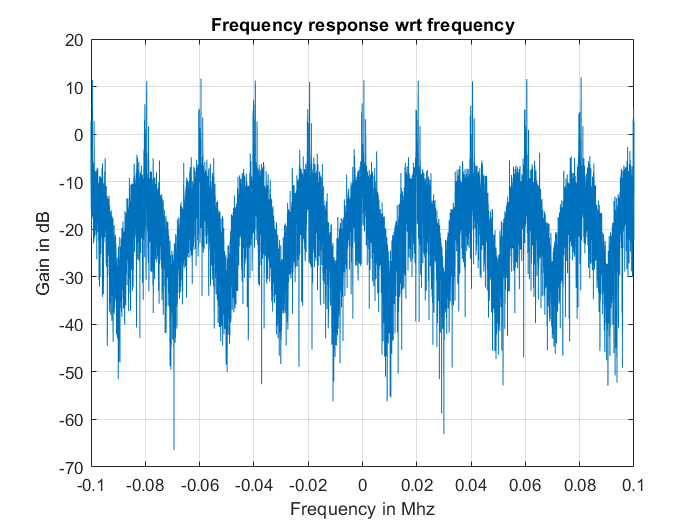



hestFd =zeros(nfft,n);


    for j = 1:n
        
        hestFd(:,j) = yfd(:,j)./x0_fd;
    end


fresp = reshape(hestFd,[nfft*n,1]);

% Plotting the channel 

f = linspace(-fs*1e-6,1e-6*fs,n*nfft);
plot(f,pow2db(abs(fresp).^2),"LineStyle","-","LineWidth",0.5)
title("Frequency response wrt frequency")
ylabel("Gain in dB")
xlabel("Frequency in Mhz")
xlim([-0.1 0.1])
grid on

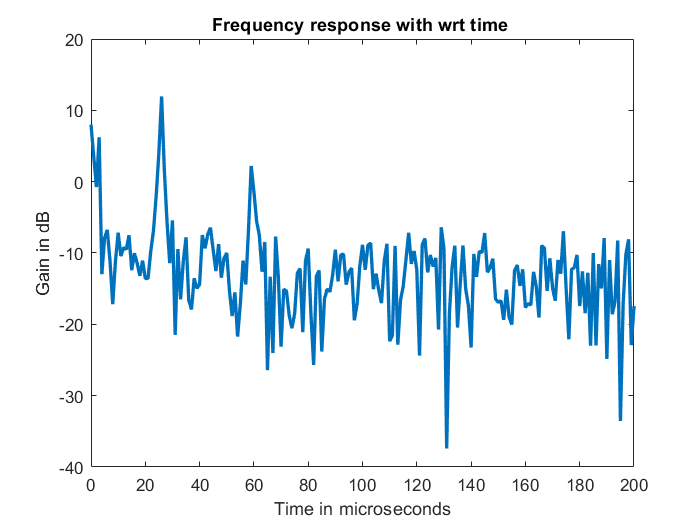


% plotting in time domain 

t = linspace(0,1e6*n*nfft/fs,n*nfft);
plot(t,pow2db(abs(fresp).^2),"LineStyle","-","LineWidth",2)
title("Frequency response with wrt time ")
ylabel("Gain in dB")
xlabel("Time in microseconds")
xlim([0 200])